# **《自然》杂志上的电磁隐身衣演示**

**        2015年，Zhou 等在《nature》子刊《Scientific Report》上发表论文，使用的方法类似于“静电型隐形衣”。他们采用的隐形装置内部的PEC导体柱被挖空，形成一个半径为c的空腔，用于容纳待“隐形”的目标。****由于导体内部电场处处为零****，因此这个设计与前面**[**“静电型隐形衣”**](matlab:open('..\B 第二章 静电场\B4_Electrostatic_Invisibility_Cloak.mlx'))**给出的推导无任何差异。仿真结果验证了设计的正确性。**

**        假设空心超导柱的外径**$a=0\ldotp 2$**，介质柱套外径**$b=0\ldotp 4$**，背景材料的介电常数为**$\varepsilon_b =1$**，计算可知柱套的介电常数为**$\varepsilon_2 =0\ldotp 6$**。**

**        用pdetool仿真：**

- **仅有空心超导柱时的电势分布仿真**

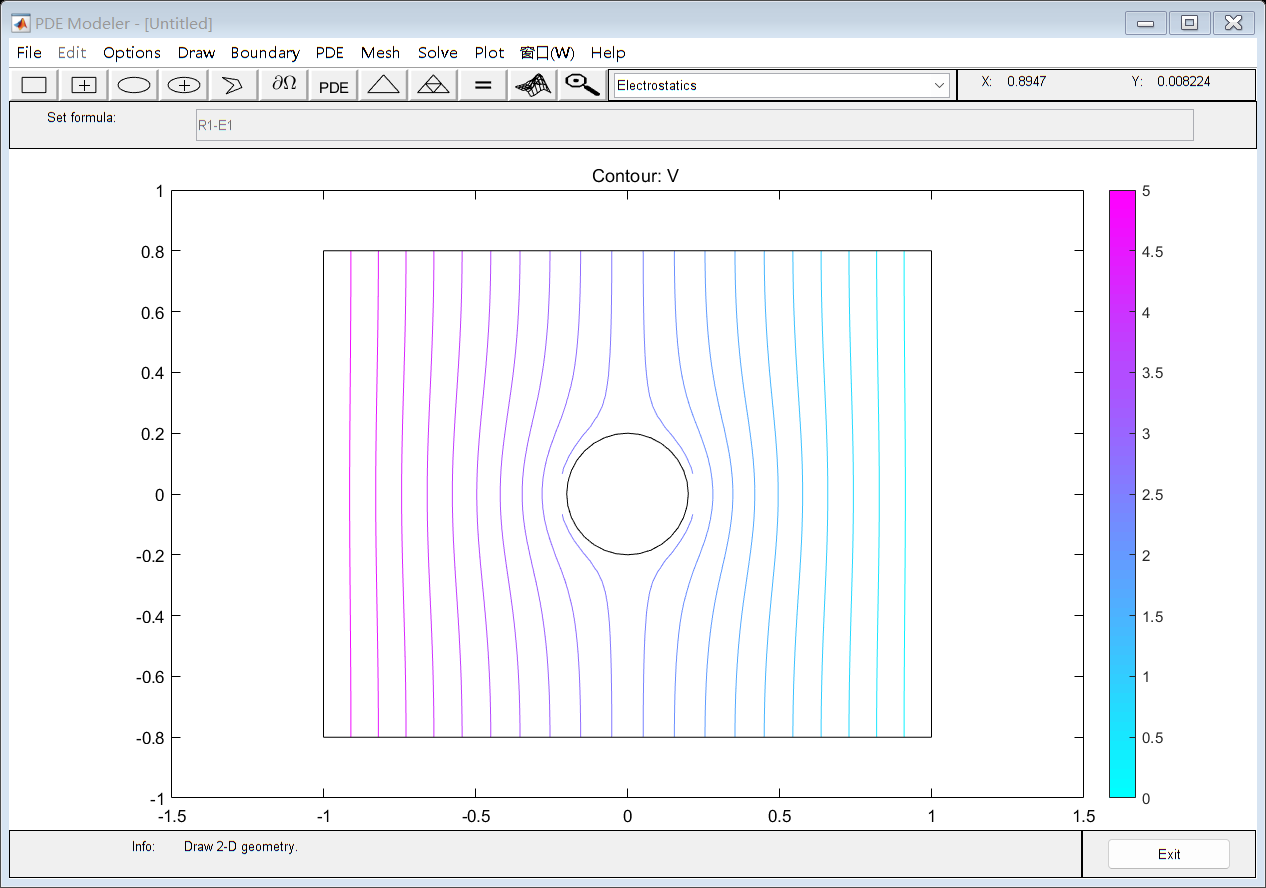

 Without_Invisibility_Cloak

**        以上为空气中仅有超导柱的情况，可以看出，由于超导圆柱的存在，空间的电势分布都不再均匀。**

- **用隐形材料包裹空心超导柱时的电势分布**

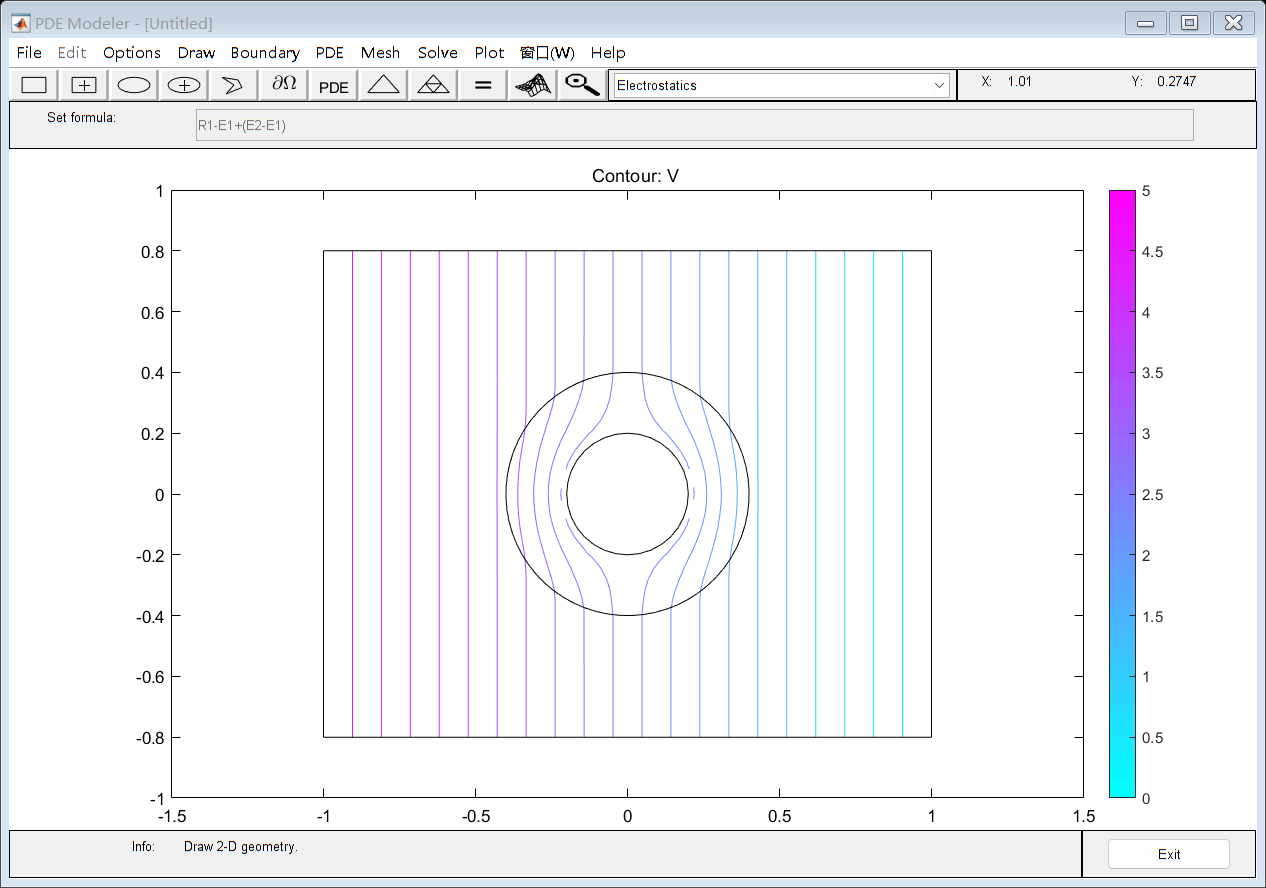

With_Invisibility_Cloak

**        当采用了隐形材料包裹超导柱之后，空间背景中的电势分布又变得均匀，所有扰动都发生在柱套内部。因此，达到了在静电场中隐形的目的。**

- **使用PDETool仿真生成的函数**

function  With_Invisibility_Cloak
    [pde_fig,ax]=pdeinit;
    pdetool('appl_cb',5);
    set(ax,'DataAspectRatio',[1 1 1]);
    set(ax,'PlotBoxAspectRatio',[1.5 1 1]);
    set(ax,'XLim',[-1.5 1.5]);
    set(ax,'YLim',[-1 1]);
    set(ax,'XTickMode','auto');
    set(ax,'YTickMode','auto');
    
    % Geometry description:
    pderect([-1 1 0.80000000000000004 -0.80000000000000004],'R1');
    pdeellip(0,0,0.20000000000000001,0.20000000000000001,...
    0,'E1');
    pdeellip(0,0,0.40000000000000002,0.40000000000000002,...
    0,'E2');
    set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','R1-E1+(E2-E1)')
    
    % Boundary conditions:
    pdetool('changemode',0)
    pdesetbd(8,...
    'dir',...
    1,...
    '1',...
    '2.50')
    pdesetbd(7,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(6,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(5,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(4,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(3,...
    'dir',...
    1,...
    '1',...
    '5')
    pdesetbd(2,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(1,...
    'dir',...
    1,...
    '1',...
    '0')
    
    % Mesh generation:
    setappdata(pde_fig,'Hgrad',1.3);
    setappdata(pde_fig,'refinemethod','regular');
    setappdata(pde_fig,'jiggle',char('on','mean',''));
    setappdata(pde_fig,'MesherVersion','preR2013a');
    pdetool('initmesh')
    pdetool('refine')
    pdetool('refine')
    
    % PDE coefficients:
    pdeseteq(1,...
    '1.0!0.6',...
    '0.0!0.0',...
    '0!0',...
    '1.0!1.0',...
    '0:10',...
    '0.0',...
    '0.0',...
    '[0 100]')
    setappdata(pde_fig,'currparam',...
    ['1.0!0.6';...
    '0!0    '])
    
    % Solve parameters:
    setappdata(pde_fig,'solveparam',...
    char('0','6144','10','pdeadworst',...
    '0.5','longest','0','1E-4','','fixed','Inf'))
    
    % Plotflags and user data strings:
    setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 1 1 1 0 0 1 0 1 0 0 0 1]);
    setappdata(pde_fig,'colstring','');
    setappdata(pde_fig,'arrowstring','');
    setappdata(pde_fig,'deformstring','');
    setappdata(pde_fig,'heightstring','');
    
    % Solve PDE:
    pdetool('solve')
end
function  Without_Invisibility_Cloak
    [pde_fig,ax]=pdeinit;
    pdetool('appl_cb',5);
    set(ax,'DataAspectRatio',[1 1 1]);
    set(ax,'PlotBoxAspectRatio',[1.5 1 1]);
    set(ax,'XLim',[-1.5 1.5]);
    set(ax,'YLim',[-1 1]);
    set(ax,'XTickMode','auto');
    set(ax,'YTickMode','auto');
    
    % Geometry description:
    pderect([-1 1 0.80000000000000004 -0.80000000000000004],'R1');
    pdeellip(0,0,0.20000000000000001,0.20000000000000001,...
    0,'E1');
    set(findobj(get(pde_fig,'Children'),'Tag','PDEEval'),'String','R1-E1')
    
    % Boundary conditions:
    pdetool('changemode',0)
    pdesetbd(8,...
    'dir',...
    1,...
    '1',...
    '2.50')
    pdesetbd(7,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(6,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(5,...
    'dir',...
    1,...
    '1',...
    '2.5')
    pdesetbd(4,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(3,...
    'dir',...
    1,...
    '1',...
    '5')
    pdesetbd(2,...
    'neu',...
    1,...
    '0',...
    '0')
    pdesetbd(1,...
    'dir',...
    1,...
    '1',...
    '0')
    
    % Mesh generation:
    setappdata(pde_fig,'Hgrad',1.3);
    setappdata(pde_fig,'refinemethod','regular');
    setappdata(pde_fig,'jiggle',char('on','mean',''));
    setappdata(pde_fig,'MesherVersion','preR2013a');
    pdetool('initmesh')
    pdetool('refine')
    pdetool('refine')
    
    % PDE coefficients:
    pdeseteq(1,...
    '1.0!1',...
    '0.0!0.0',...
    '0!0',...
    '1.0!1.0',...
    '0:10',...
    '0.0',...
    '0.0',...
    '[0 100]')
    setappdata(pde_fig,'currparam',...
    ['1.0!1';...
    '0!0  '])
    
    % Solve parameters:
    setappdata(pde_fig,'solveparam',...
    char('0','6144','10','pdeadworst',...
    '0.5','longest','0','1E-4','','fixed','Inf'))
    
    % Plotflags and user data strings:
    setappdata(pde_fig,'plotflags',[1 1 1 1 1 1 1 1 1 0 0 1 0 1 0 0 0 1]);
    setappdata(pde_fig,'colstring','');
    setappdata(pde_fig,'arrowstring','');
    setappdata(pde_fig,'deformstring','');
    setappdata(pde_fig,'heightstring','');
    
    % Solve PDE:
    pdetool('solve')
end

- **上述分析给出了外部电场中存在金属柱金属导体内部挖空时等势线分布的两种情况，即无隐形套层和有隐形套层。可以看出，当隐形套层不发挥作用时，等势线在金属柱附近发生了弯曲、变形；而当采用隐形套层时，所有变形仅发生在套层内部，外部依旧是均匀电场。这充分证明了静电隐形的功能。**

- **参考文献：**

**                [1] Lan C, Yang Y, Geng Z, et al. Electrostatic field invisibility cloak[J]. Scientific Reports, 2015, 5(1): 16416.**